University of Science and Technology in Zewail City

Communication and Information Engineering Program

CIE 237: [Probability and Stochastic Processes - Spring 2026](https://classroom.google.com/u/1/c/ODI1MzU5NDE2MjMy)

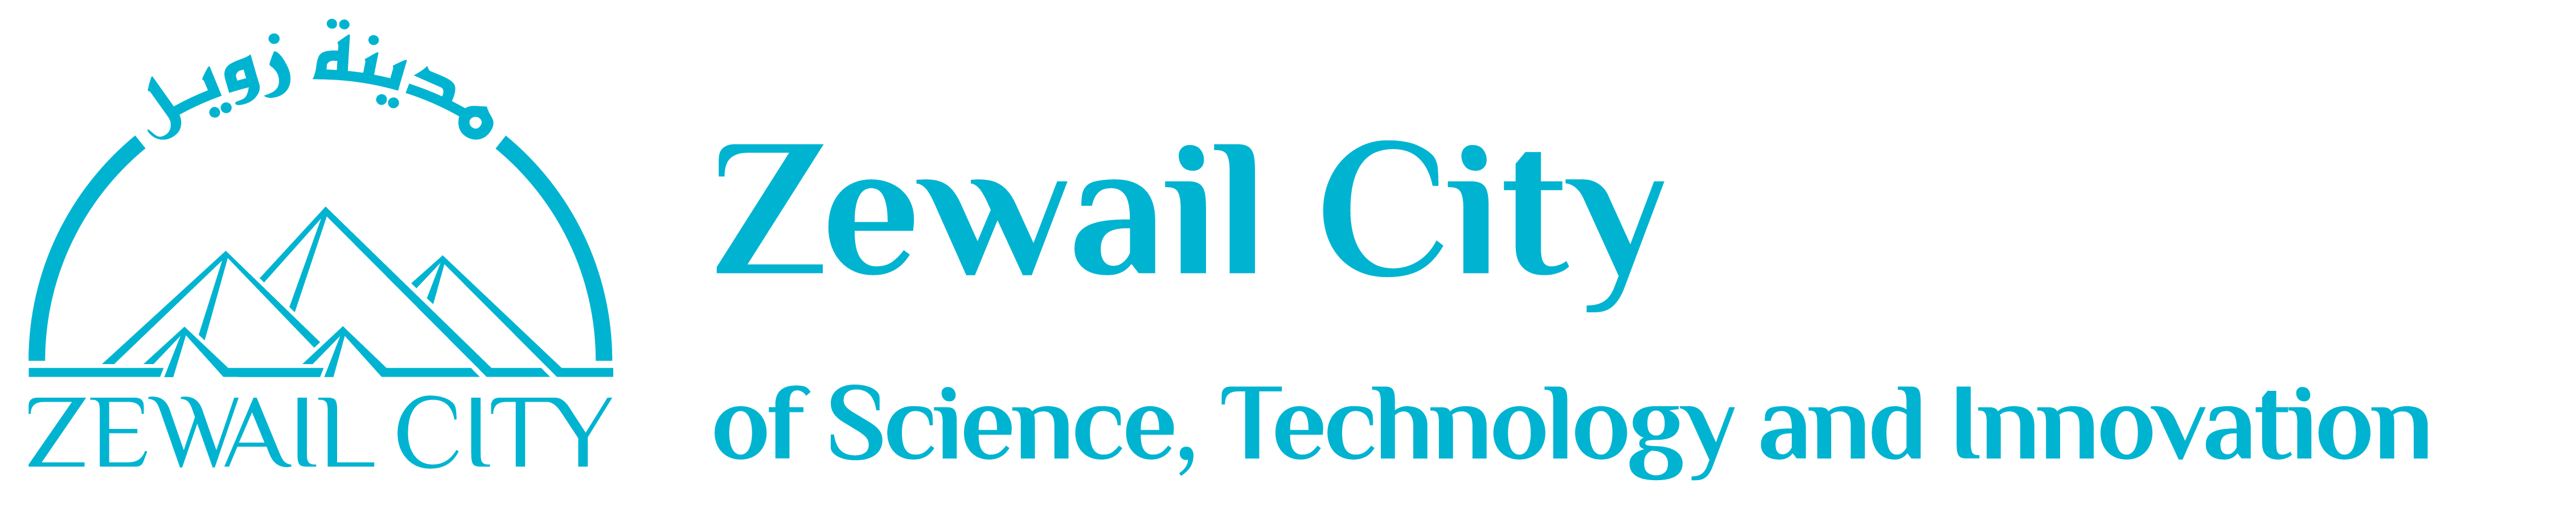

## Project Title: Performance Analysis of M-PAM with Matched Filtering

Author: Mohammed Soliman-202402280

Supervision: Prof. Ahmed Eltrass, Eng. Retaj Yousri, Eng. Heba Selim

### Simulation Parameters.

clear; clc; close all;

M_list = [2 4 8];
EbN0dB = 0:2:20;
num_symbols = 1e5;
sps = 8;
step = 1/sps;
rolloff = 0.5;
span = 6;

### Pulse Shapes.

%Rectangular
p_rect = ones(1, sps) / sqrt(sps);

%Raised Cosine
p_rcos = rcosdesign(rolloff, span, sps, 'sqrt');
p_rcos = p_rcos / norm(p_rcos);

%Triangle
p_tri = 1 - abs((-sps/2 : sps/2-1) / (sps/2));
p_tri = p_tri / norm(p_tri);

L_rect = length(p_rect);
L_rcos = length(p_rcos);
L_tri  = length(p_tri);

### Initial Storage.

nM   = length(M_list);
nSNR = length(EbN0dB);

BER_rect = zeros(nM, nSNR);  SER_rect = zeros(nM, nSNR);
BER_rcos = zeros(nM, nSNR);  SER_rcos = zeros(nM, nSNR);
BER_tri  = zeros(nM, nSNR);  SER_tri  = zeros(nM, nSNR);

BER_sim_rect = zeros(nM, nSNR);  SER_sim_rect = zeros(nM, nSNR);
BER_sim_rcos = zeros(nM, nSNR);  SER_sim_rcos = zeros(nM, nSNR);
BER_sim_tri  = zeros(nM, nSNR);  SER_sim_tri  = zeros(nM, nSNR);
EbN0_lin = 10.^(EbN0dB / 10);
theo_BER = zeros(nM, nSNR);
theo_SER = zeros(nM, nSNR);

for m = 1:nM
    M = M_list(m);
    k = log2(M);
    arg = sqrt(6 * k * EbN0_lin / (M^2 - 1));
    
    theo_SER(m,:) = 2 * (M-1)/M * 0.5 * erfc(arg / sqrt(2));
    theo_BER(m,:) = theo_SER(m,:) / k;
end

### Theoretical BER/SER.

EbN0_lin = 10.^(EbN0dB / 10);
theo_BER = zeros(nM, nSNR);
theo_SER = zeros(nM, nSNR);

for m = 1:nM
    M = M_list(m);
    k = log2(M);
    arg = sqrt(6 * k * EbN0_lin / (M^2 - 1));

    theo_SER(m,:) = 2 * (M-1)/M * 0.5 * erfc(arg / sqrt(2));
    theo_BER(m,:) = theo_SER(m,:) / k;
end

### MATLAB Simulation.

for m = 1:nM
    M = M_list(m);
    k = log2(M);

    %Constellation mapping
    d = sqrt(3 / (M^2 - 1));
    symbol_map = (-(M-1):2:(M-1)) * d;

    fprintf('Running MATLAB simulation for %d-PAM...\n', M);

    for snr = 1:nSNR
        EbN0_val = 10^(EbN0dB(snr) / 10);
        N0 = 1 / (k * EbN0_val);
        noise_std = sqrt(N0 / 2);

        sym_idx = randi([0 M-1], num_symbols, 1);
        bits = de2bi(sym_idx, k, 'left-msb');
        tx_symbols = symbol_map(sym_idx + 1)';
        up_symbols = upsample(tx_symbols, sps);

        %Rectangular
        tx_sig = conv(up_symbols, p_rect, 'full');
        rx = tx_sig + noise_std * randn(size(tx_sig));
        mf_out = conv(rx, fliplr(p_rect), 'full');
        samp = mf_out(L_rect : sps : L_rect + (num_symbols-1)*sps);
        [BER_rect(m,snr), SER_rect(m,snr)] = calc_errors(samp, tx_symbols, symbol_map, bits, k, num_symbols);

        %Raised Cosine
        tx_sig = conv(up_symbols, p_rcos, 'full');
        rx     = tx_sig + noise_std * randn(size(tx_sig));
        mf_out = conv(rx, fliplr(p_rcos), 'full');
        samp   = mf_out(L_rcos : sps : L_rcos + (num_symbols-1)*sps);
        [BER_rcos(m,snr), SER_rcos(m,snr)] = calc_errors(samp, tx_symbols, symbol_map, bits, k, num_symbols);

        %Triangle
        tx_sig = conv(up_symbols, p_tri, 'full');
        rx     = tx_sig + noise_std * randn(size(tx_sig));
        mf_out = conv(rx, fliplr(p_tri), 'full');
        samp   = mf_out(L_tri : sps : L_tri + (num_symbols-1)*sps);
        [BER_tri(m,snr), SER_tri(m,snr)] = calc_errors(samp, tx_symbols, symbol_map, bits, k, num_symbols);
    end
end

Running MATLAB simulation for 2-PAM...
Running MATLAB simulation for 4-PAM...
Running MATLAB simulation for 8-PAM...


### Simulink Simulation.


load_system('Simulink_Circuit');
set_param('Simulink_Circuit', 'StopTime', '2e5', 'FastRestart', 'off');

%Loading blocks
mod_blocks = find_system('Simulink_Circuit', 'MaskType', 'M-PAM Modulator Baseband');
demod_blocks = find_system('Simulink_Circuit', 'MaskType', 'M-PAM Demodulator Baseband');
rand_blocks = find_system('Simulink_Circuit', 'MaskType', 'Random Integer Generator');
itb_blocks = find_system('Simulink_Circuit', 'MaskType', 'Integer to Bit Converter');
awgn_blocks = find_system('Simulink_Circuit', 'MaskType', 'AWGN Channel');
tx_filt = find_system('Simulink_Circuit', 'MaskType', 'Raised Cosine Transmit Filter');
rx_filt = find_system('Simulink_Circuit', 'MaskType', 'Raised Cosine Receive Filter');

pulse_labels = {'Rectangular', 'Raised Cosine', 'Triangle'};

for p_idx = 1:3
    fprintf('\nRunning Simulink: %s pulse...\n', pulse_labels{p_idx});

    if p_idx == 1 %Rectangular
        rect_coeff_str = mat2str(p_rect);
        for i = 1:length(tx_filt)
            set_param(tx_filt{i}, 'FilterType', 'Custom', 'CustomFilterCoefficients', rect_coeff_str);
            set_param(rx_filt{i}, 'FilterType', 'Custom', 'CustomFilterCoefficients', rect_coeff_str);
        end
        rxDelaySER_base = floor(L_rect / 2 / sps);

    elseif p_idx == 2 %Raised Cosine
        for i = 1:length(tx_filt)
            set_param(tx_filt{i}, 'RolloffFactor', num2str(rolloff), 'FilterType', 'Square Root');
            set_param(rx_filt{i}, 'RolloffFactor', num2str(rolloff), 'FilterType', 'Square Root');
        end
        rxDelaySER_base = span;

    elseif p_idx == 3 %Triangle
        tri_coeff_str = mat2str(p_tri);
        for i = 1:length(tx_filt)
            set_param(tx_filt{i}, 'FilterType', 'Custom', 'CustomFilterCoefficients', tri_coeff_str);
            set_param(rx_filt{i}, 'FilterType', 'Custom', 'CustomFilterCoefficients', tri_coeff_str);
        end
        rxDelaySER_base = floor(L_tri / 2 / sps);
    end

    %Looping over Modulation Orders
    for m = 1:nM
        M = M_list(m);
        k = log2(M);

        fprintf('  Simulating %d-PAM\n', M);

        for i = 1:length(mod_blocks),   set_param(mod_blocks{i}, 'M', num2str(M)); end
        for i = 1:length(demod_blocks), set_param(demod_blocks{i}, 'M', num2str(M)); end
        for i = 1:length(rand_blocks),  set_param(rand_blocks{i}, 'SetSize', num2str(M)); end
        for i = 1:length(itb_blocks),   set_param(itb_blocks{i}, 'Nbits', num2str(k)); end
        for i = 1:length(awgn_blocks),  set_param(awgn_blocks{i}, 'BitsPerSymbol', num2str(k)); end

        for snr = 1:nSNR
            assignin('base', 'M', M);

            assignin('base', 'EbNo', EbN0dB(snr) + 10*log10(sps));

            assignin('base', 'rolloff', rolloff);
            assignin('base', 'span', span);
            assignin('base', 'N', sps);

            assignin('base', 'rxDelaySER_base', rxDelaySER_base);

            simOut = sim('Simulink_Circuit.slx');

            try
                b_val = simOut.ErrorVecBER;
                s_val = simOut.ErrorVecSER;

                if isa(b_val, 'timeseries')
                    b_val = b_val.Data(end, 1);
                    s_val = s_val.Data(end, 1);
                else
                    b_val = b_val(1);
                    s_val = s_val(1);
                end
            catch
                warning('Error.');
                b_val = NaN; s_val = NaN;
            end

            if p_idx == 1
                BER_sim_rect(m, snr) = b_val; SER_sim_rect(m, snr) = s_val;
            elseif p_idx == 2
                BER_sim_rcos(m, snr) = b_val; SER_sim_rcos(m, snr) = s_val;
            else
                BER_sim_tri(m, snr)  = b_val; SER_sim_tri(m, snr)  = s_val;
            end
        end
    end
end


Running Simulink: Rectangular pulse...


  Simulating 2-PAM
  Simulating 4-PAM
  Simulating 8-PAM



Running Simulink: Raised Cosine pulse...


  Simulating 2-PAM
  Simulating 4-PAM
  Simulating 8-PAM



Running Simulink: Triangle pulse...


  Simulating 2-PAM
  Simulating 4-PAM
  Simulating 8-PAM


close_system('Simulink_Circuit', 0);

### Calculation and Plotting Functions.

function [ber, ser] = calc_errors(samp, tx_symbols, symbol_map, bits, k, N)
dec = zeros(N, 1);
for i = 1:N
    [~, min_idx] = min(abs(samp(i) - symbol_map));
    dec(i) = symbol_map(min_idx);
end

%SER calculation
ser = sum(tx_symbols(:) ~= dec(:)) / N;

%BER calculation
[~, dec_idx] = ismember(dec, symbol_map);
dec_bits = de2bi(dec_idx - 1, k, 'left-msb');
ber = sum(bits(:) ~= dec_bits(:)) / (N * k);
end

function plot_panel(EbN0dB, sim_data, theo_data, slnk_data, labels, ylbl)
colors  = {'b', 'r', 'g'};
markers = {'o', 's', 'd'};

ax = gca;
ax.YScale = 'log'; 
hold on; grid on;

for i = 1:3
    semilogy(EbN0dB, sim_data(i,:), [colors{i} '-'], 'Marker', markers{i}, 'LineWidth', 1.5, 'DisplayName', [labels{i} ' MATLAB']);
    semilogy(EbN0dB, theo_data(i,:), [colors{i} '--'], 'LineWidth', 1.2, 'DisplayName', [labels{i} ' Theory']);
    semilogy(EbN0dB, slnk_data(i,:), [colors{i} '-'], 'Marker', '*', 'LineWidth', 1.5, 'DisplayName', [labels{i} ' Simulink']);
end

xlabel('E_b/N_0 (dB)');
ylabel(ylbl);
ylim([1e-5 1]);
xlim([0 20]);
legend('Location', 'southwest', 'FontSize', 7, 'NumColumns', 3);
end

### Plots.

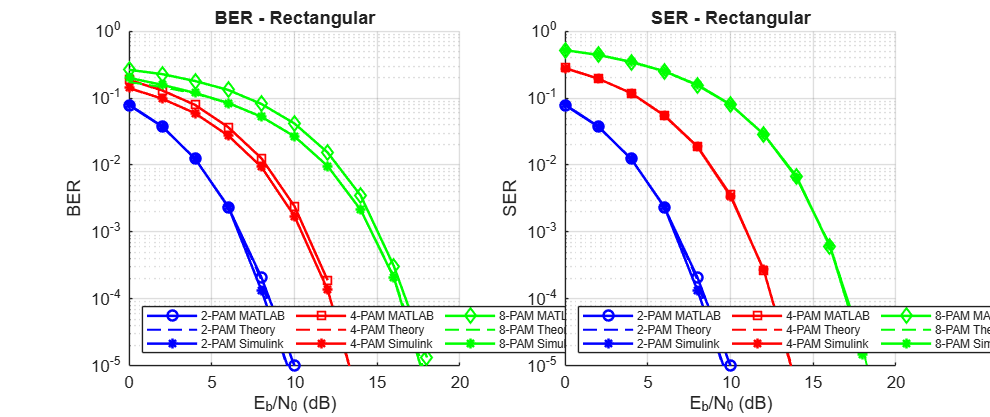

labels = {'2-PAM', '4-PAM', '8-PAM'};

%Rectangular Figure
figure('Name', 'Rectangular Pulse', 'Position', [80 500 1000 420]);
subplot(1,2,1); plot_panel(EbN0dB, BER_rect, theo_BER, BER_sim_rect, labels, 'BER'); title('BER - Rectangular');
subplot(1,2,2); plot_panel(EbN0dB, SER_rect, theo_SER, SER_sim_rect, labels, 'SER'); title('SER - Rectangular');

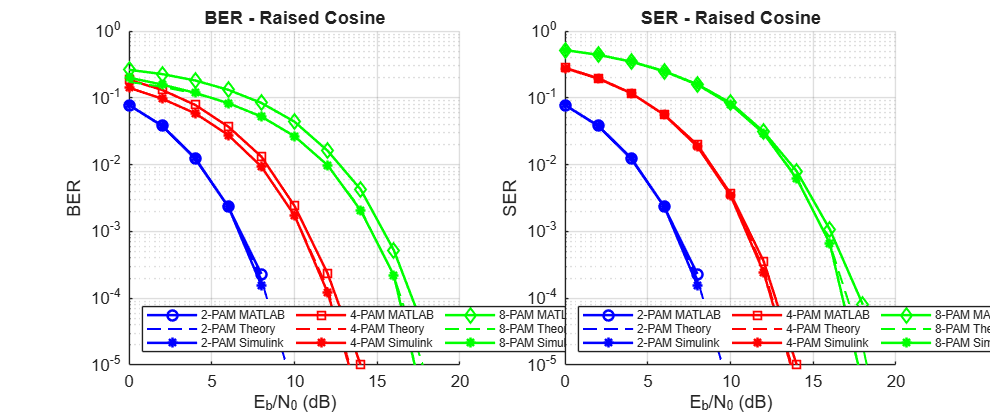

%Raised Cosine Figure
figure('Name', 'Raised Cosine Pulse', 'Position', [100 50 1000 420]);
subplot(1,2,1); plot_panel(EbN0dB, BER_rcos, theo_BER, BER_sim_rcos, labels, 'BER'); title('BER - Raised Cosine');
subplot(1,2,2); plot_panel(EbN0dB, SER_rcos, theo_SER, SER_sim_rcos, labels, 'SER'); title('SER - Raised Cosine');

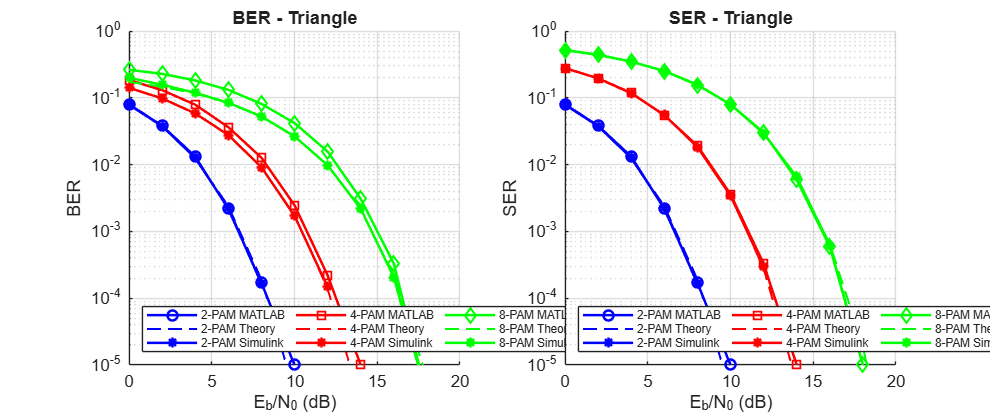

%Triangle Figure
figure('Name', 'Triangle Pulse', 'Position', [120 300 1000 420]);
subplot(1,2,1); plot_panel(EbN0dB, BER_tri, theo_BER, BER_sim_tri, labels, 'BER'); title('BER - Triangle');
subplot(1,2,2); plot_panel(EbN0dB, SER_tri, theo_SER, SER_sim_tri, labels, 'SER'); title('SER - Triangle');